metadatos=edfinfo('r01.edf')

metadatos =   edfinfo with properties:

              Filename: "r01.edf"
           FileModDate: "22-Mar-2024 16:14:00"
              FileSize: 3061792
               Version: "0"
               Patient: "r01 F X X"
             Recording: "Startdate X X X Komporel"
             StartDate: "01.01.11"
             StartTime: "00.00.00"
           HeaderBytes: 1792
              Reserved: "EDF+C"
        NumDataRecords: 60
    DataRecordDuration: 5 sec
            NumSignals: 5
          SignalLabels: [5x1 string]
       TransducerTypes: [5x1 string]
    PhysicalDimensions: [5x1 string]
           PhysicalMin: [5x1 double]
           PhysicalMax: [5x1 double]
            DigitalMin: [5x1 double]
            DigitalMax: [5x1 double]
             Prefilter: [5x1 string]
            NumSamples: [5x1 double]
        SignalReserved: [5x1 string]
           Annotations: [644x2 timetable]


datos=edfread('r01.edf')

datos = 60x5 timetable
    Record Time       Direct_1           Abdomen_1          Abdomen_2          Abdomen_3          Abdomen_4   
    ___________    _______________    _______________    _______________    _______________    _______________

    0 sec          {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}
    5 sec          {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}
    10 sec         {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}
    15 sec         {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}    {5000x1 double}
    20 sec         {5

datosAbdomen_1=edfread('r01.edf','SelectedSignals','Abdomen_1')

datosAbdomen_1 = 60x1 timetable
    Record Time       Abdomen_1   
    ___________    _______________

    0 sec          {5000x1 double}
    5 sec          {5000x1 double}
    10 sec         {5000x1 double}
    15 sec         {5000x1 double}
    20 sec         {5000x1 double}
    25 sec         {5000x1 double}
    30 sec         {5000x1 double}
    35 sec         {5000x1 double}
    40 sec         {5000x1 double}
    45 sec         {5000x1 double}
    50 sec         {5000x1 double}
    55 sec         {5000x1 double}
    60 sec         {5000x1 double}
    65 sec         {5000x1 double}
    70 sec         {5000x1 double}
    75 sec         {5000x1 doubl

datosAbdomen_1_matriz=table2array(datosAbdomen_1)

datosAbdomen_1_matriz = 60x1 cell array
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}
    {5000x1 double}


datosAbdomen_1_SI=vertcat(datosAbdomen_1_matriz{1:2,:})

datosAbdomen_1_SI =    -8.8501
  -13.9502
  -18.7503
  -23.4504
  -27.9504
  -32.8505
  -38.1506
  -43.8507
  -49.3508
  -54.0508



fm=1000

fm = 1000

figure(1)
t=0:1/fm:5

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


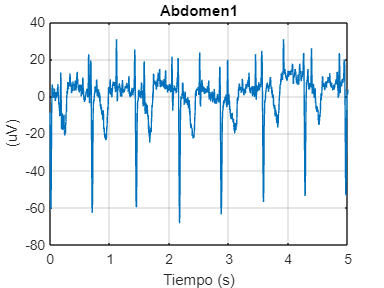

plot(t,datosAbdomen_1_SI(1:5001)) 
title('Abdomen1')
xlabel('Tiempo (s)')
ylabel('(uV)') 
grid






Como leer archivo de .qrs

Unrecognized function or variable 'Como'.

preguntar GitHub